This live-script runs solvers for the 2D acoustics equations via staggered grid FD methods.

In particular, the output pressure field is only stored at a horizontal or vertical line of spatial points, or at a single point.

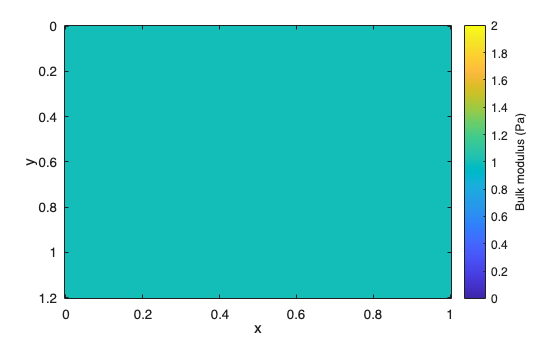

clear
close all
clc

% Computational space grids
dom_x = [0,1];
dom_y = [0,1.2];
Nx = 151;
Ny = 161;

grid_x_primal = Grid1DUnifPrimal(dom_x,Nx);
grid_y_primal = Grid1DUnifPrimal(dom_y,Ny);
grid_x_dual = Grid1DUnifDual(grid_x_primal);
grid_y_dual = Grid1DUnifDual(grid_y_primal);

gsp_P  = GridSpace2D( grid_x_primal, grid_y_primal);
gsp_Vx = GridSpace2D( grid_x_dual,   grid_y_primal);
gsp_Vy = GridSpace2D( grid_x_primal, grid_y_dual);

% Medium parameters
medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
[kappa,betax,betay,wspeed,cMax] = sampleMedium2D(gsp_P,medium);

kappa.plot;

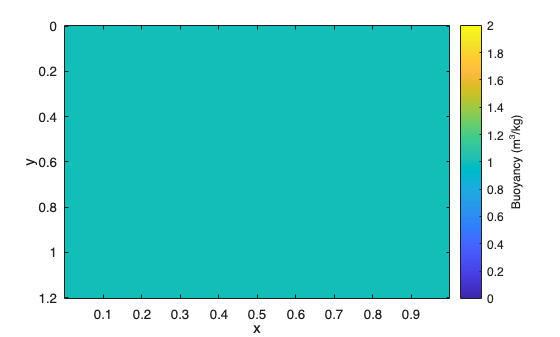

betax.plot;

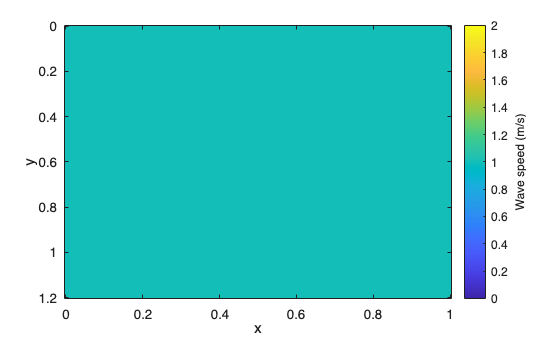

wspeed.plot;


% Computational time grid
dom_t = [0,1];
CFL = 0.9;
dt = CFL*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2)));
Nt = ceil(diff(dom_t)/dt)+1;
dt = diff(dom_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
times = dom_t(1):dt:dom_t(2);

% Output locations and times
% Case with a horizontal line of receivers
grid_x_out = Grid1DUnifPrimal([0,0.5],11);
y_out = 0.3;
grid_y_out = Grid1D(dom_y,y_out);

gsp_out = GridSpace2D(grid_x_out,grid_y_out);
times_out = linspace(dom_t(1),dom_t(2),81);

% Multipole point source
src_c = [0.35,0.45];
tc = 0.2;

monopole = MultipoleTerm2D( ...
    src_c,[0,0], ...
    @(t) exp(-((tc)/0.025).^2), ...
    Amplitude=1,TargetField="pressure");

dipoleX = MultipoleTerm2D( ...
    src_c,[1,0], ...
    @(t) RickerWave(t,tc,10), ...
    Amplitude=gsp_P.h(1), ...
    TargetField="pressure");

multipole = MultipoleSource2D( ...
    [monopole,dipoleX], ...
    ApproximationOrder=4);
source = multipole.discretize(gsp_P,gsp_Vx,gsp_Vy);
% Initializing PML
pml = PML2D( ...
    WidthLeft=0.15, ...
    WidthRight=0.15, ...
    WidthBottom=0.15, ...
    WidthTop=0.15, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Zero initial conditions
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% Initialize solver
solver = AcousticSolver2D_PML( ...
    gsp_P,times, ...
    gsp_out,times_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);
